# TP 3 

# Partie 1 : Bruits

## Question 1 :

### Se familiariser avec le bruit Gaussien. Pour cela :

Créer une image grise (256x256) dont l'intensité du pixel vaut 0,5, puis ajouter un bruit Gaussien de moyenne nulle et de variance 0.01

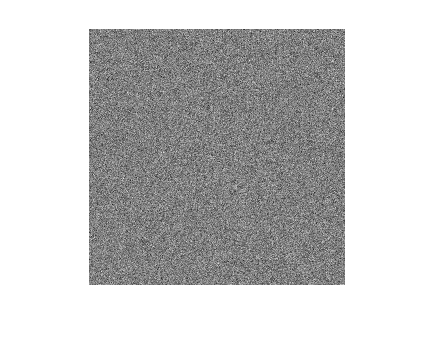

 %Création de l'image grise à l'aide de ones() précédé d'un facteur
% adéquate
n=256;
Igrise=0.5*ones(n);
% Ajout du bruit gaussien à l'aide de imnoise(), mettre une moyenne à 0
% et un ecart-type de 0,1
%imnoise(image,'gaussian',moyenne,variance) où variance = sigma^2

IGauss=imnoise(Igrise,'gaussian',0,0.01);
% Affichage de l'image bruitée et de son histogramme
figure;
imshow(IGauss)

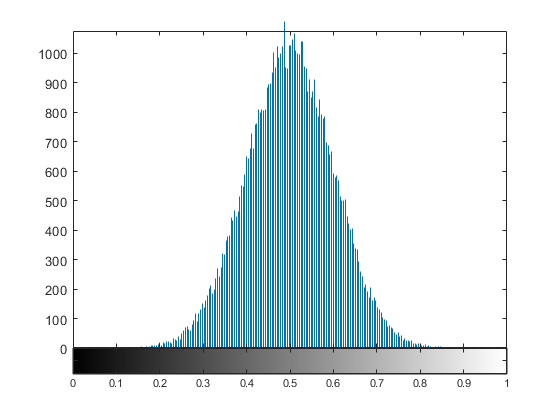

figure;
imhist(IGauss)

Changer la valeur d'écart-type et de moyenne, puis commenter l'impact de ces paramètres sur l'histogramme.

## Question 2 : 

### Déterminer la nature du bruit dans les différentes zones de l'image stockée dans 'NoisyImage'. Pour cela :

Charger l'image et l'afficher :

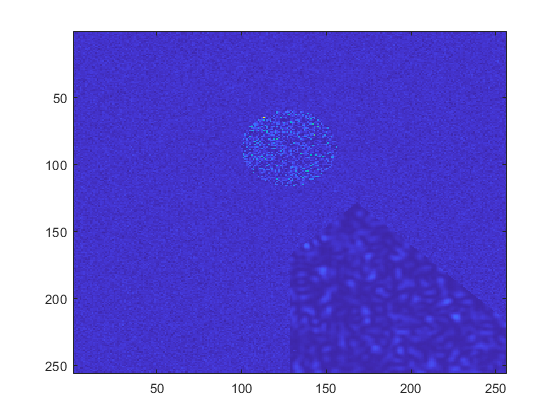

% Chargement de l'image à l'aide de load, vérifier que NoisyImage est
% stockée dans le Workspace
load NoisyImage.mat
%NoisyImage=NoisyImage;
% Affichage de l'image à l'aide de imagesc()
figure;
imagesc(NoisyImage)

Pourquoi utiliser imagesc plutot que imshow? 

v_max=max(NoisyImage(:))

v_max = 594.2802

v_min=min(NoisyImage(:))

v_min = 0.0059

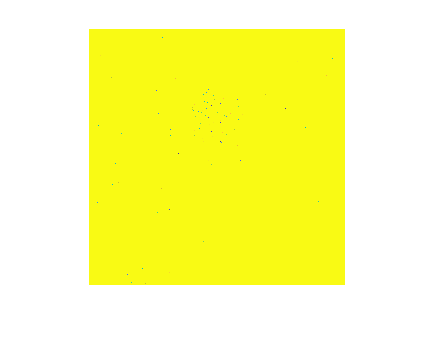

figure, imshow(NoisyImage),colormap('parula')

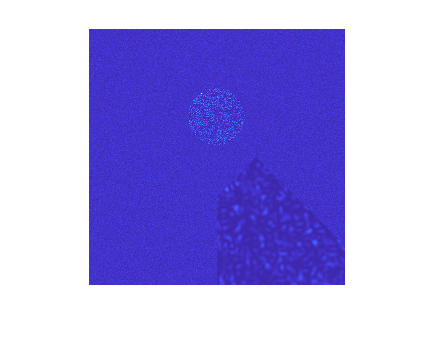

figure,imshow(NoisyImage,[v_min v_max]),colormap('parula')

Selection des 3 zones :

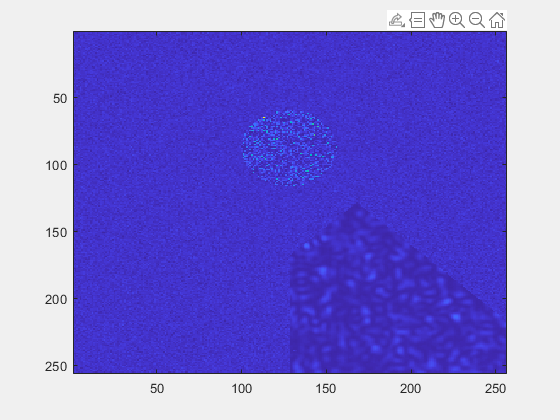

% Sélection des zones :  extraction à l'aide de imcrop -> Sélectionner une partie
% de l'image en cliquant dessus puis double cliquez pour valider la
% sélection.
figure;
imagesc(NoisyImage)
% zone ronde :
rond = imcrop;

% coin bas droit:
coinBasDroit = imcrop;

% Fond:
fond = imcrop;

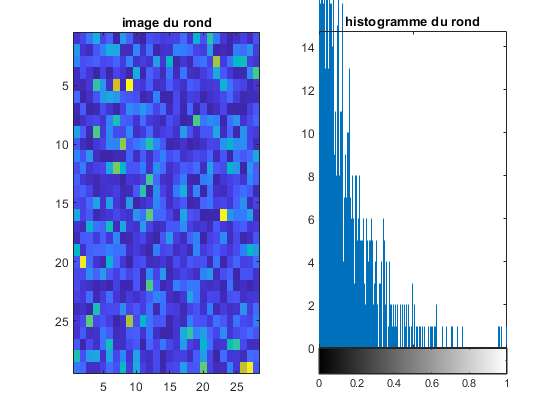

%Affichage des trois sélections et de leur histogramme sur trois sous-figures

figure;
subplot(1,2,1);
imagesc(rond)
title("image du rond")
subplot(1,2,2);
imhist(rond / max(rond(:)))
title("histogramme du rond")

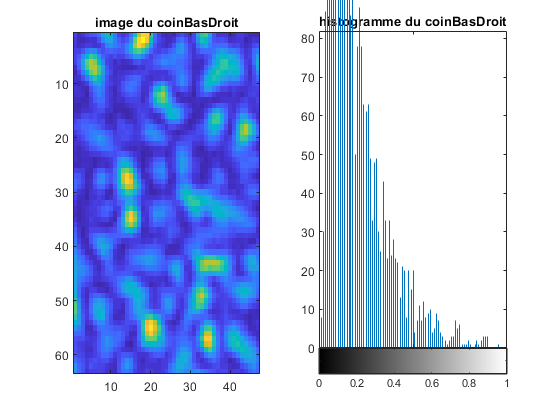

 
figure;
subplot(1,2,1);
imagesc(coinBasDroit)
title("image du coinBasDroit")
subplot(1,2,2);
imhist(coinBasDroit / max(coinBasDroit(:)))
title("histogramme du coinBasDroit")

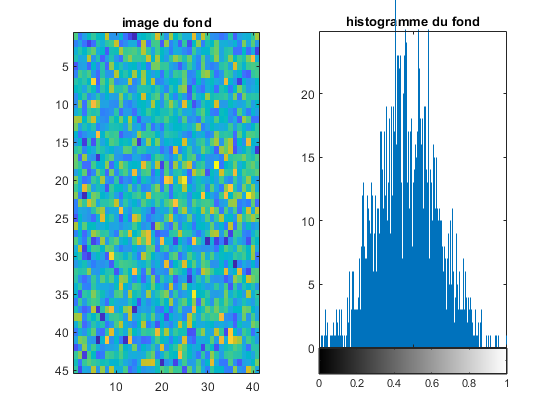


figure
subplot(1,2,1);
imagesc(fond)
title("image du fond")
subplot(1,2,2);
imhist(fond / max(fond(:)))
title("histogramme du fond")

Conclure sur la nature des 3 bruits observés.

# Partie 2 : Filtrage

## Question 3 :

### Ajouter du bruit gaussien de moyenne sur Lena, puis afficher en vis à vis l'image de base et l'image bruitée. Pour cela :

Stocker l'image en noir et blanc de Lena dans LenaUint8 puis bruiter la à l'aide de imnoise()

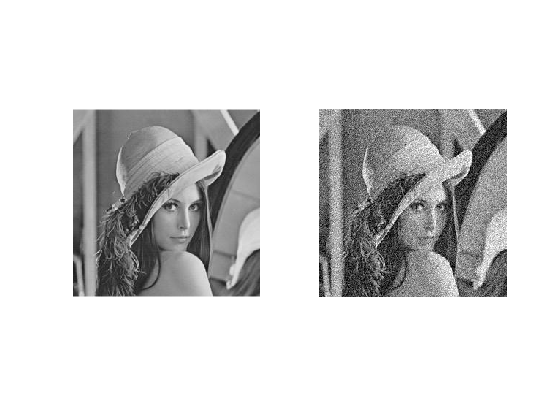

% Stockage de l'image dans LenaUint8 en noir et blanc
LenaUnit8=rgb2gray(imread('Lena.jpg'));

% Bruitage
LenaBruit=imnoise(LenaUnit8,'gaussian');

% Affichage des deux images avec subplot
figure;
subplot(1,2,1)
imshow(LenaUnit8)
subplot(1,2,2)
imshow(LenaBruit)

Cette image de Lena bruitée sera l'image de départ pour les travaux suivants. Penser à l'enregistrer sous un nom explicite.

## Question 4 :

### Appliquer le filtre moyenneur 3x3 à Lena bruitée. Comparer l'image filtrée et l'image de base, un profil d'intensité de pixels, et enfin leur TF. Pour cela :

Créer le filtre moyenneur puis l'appliquer à Lena  :

% Création du filtre
filtre3x3=1/9*[1 1 1;1 1 1;1 1 1];
%ou filtre3x3=1/9*ones(3,3);
% Appliquer à Lena bruitée grace à filter2() puis normaliser 
LenaFiltre=filter2(filtre3x3,LenaBruit,'same');
%LenaFiltre=imfilter(double(LenaBruit),filtre3x3,'same');
LenaFiltre=LenaFiltre/max(LenaFiltre(:)); 


Affichage des différents résultats

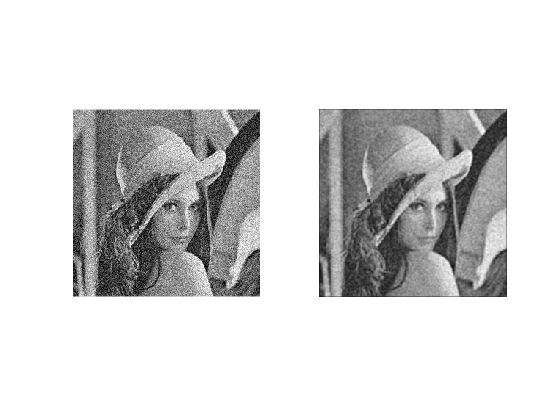

% Affichage des deux images en vis à vis
figure;
subplot(1,2,1)
imshow(LenaBruit)
subplot(1,2,2)
imshow(LenaFiltre)

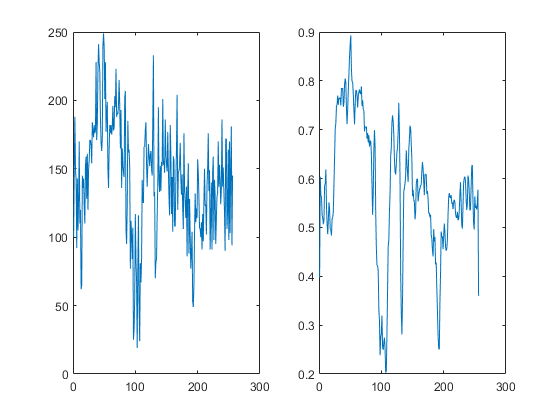

% Extraction d'un profil de pixel
profil=LenaBruit(:,124);
profilFiltre=LenaFiltre(:,124);
% Affichage des profils de pixels
figure;
subplot(1,2,1)
plot(profil)
subplot(1,2,2)
plot(profilFiltre)

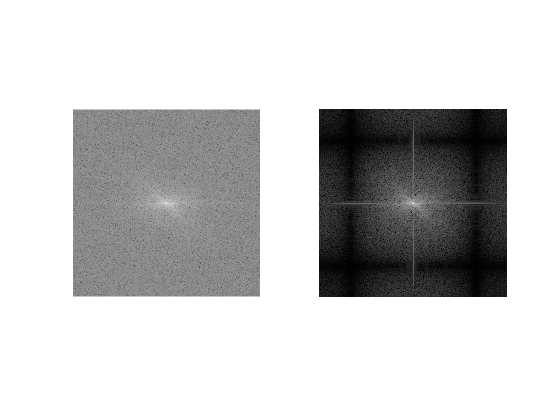

% Calcul des TF, passage au log puis normalisation 
TFBruit=abs(fftshift(fft2(LenaBruit)));
TFBruit=log(1+TFBruit);
TFBruit=TFBruit/max(TFBruit(:));
TFFiltre=abs(fftshift(fft2(LenaFiltre)));
TFFiltre=log(1+TFFiltre);
TFFiltre=TFFiltre/max(TFFiltre(:));
% Affichage des TF 
figure;
subplot(1,2,1)
imshow(TFBruit)
subplot(1,2,2)
imshow(TFFiltre)

## Question 5 :

### A l'aide d'une boucle, réitérer avec des filtres 3x3 5x5 9x9 et 15x15 puis intérpréter les résultats, notament la TF. Pour cela :

Créer la liste taille :

taille=[3 5 9 15];
m=length(taille);

Boucle  :

step = 3

step = 5

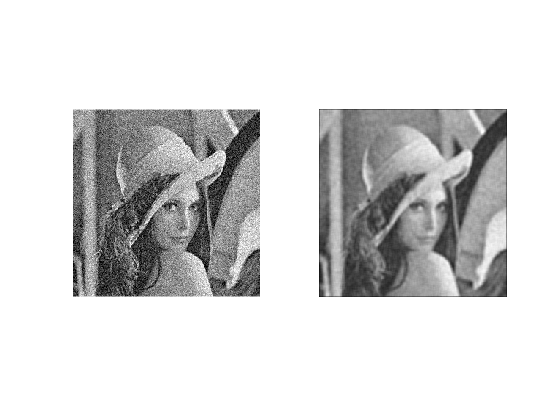

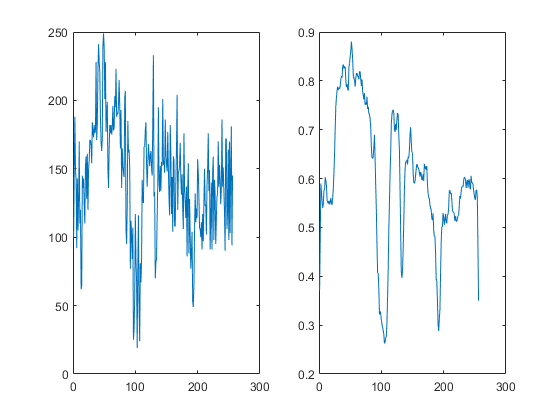

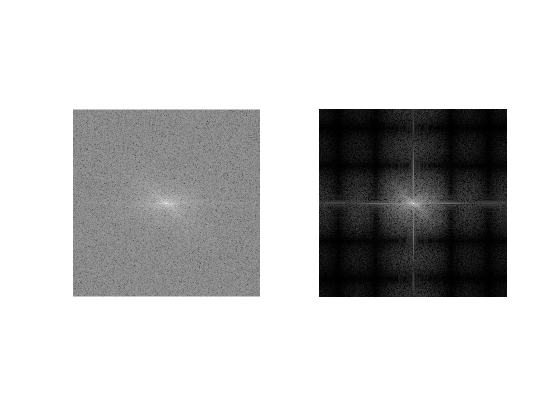

step = 9

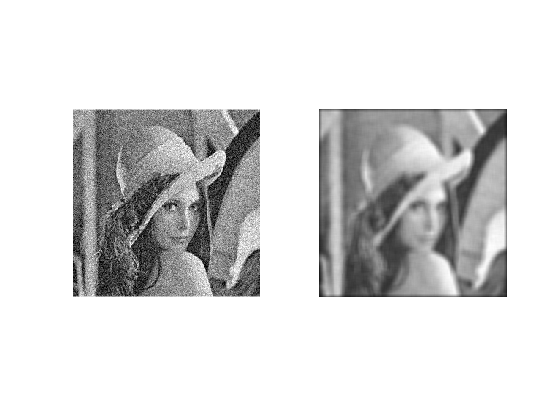

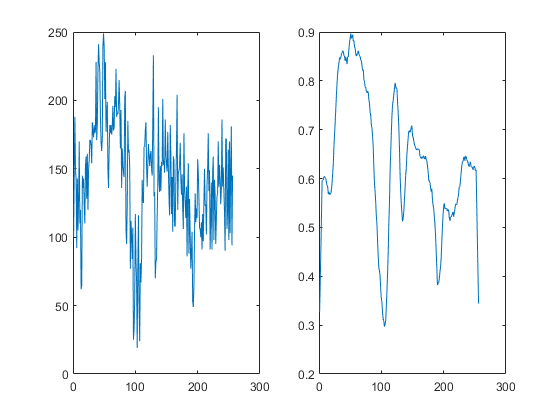

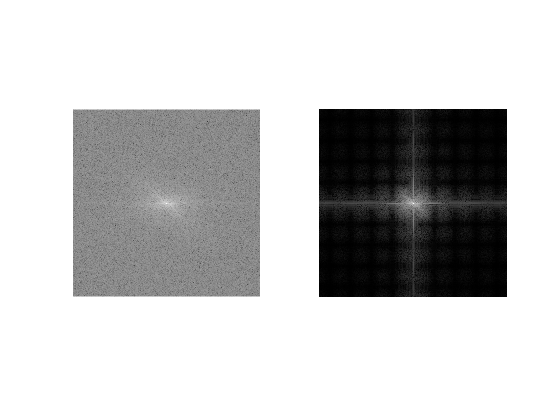

step = 15

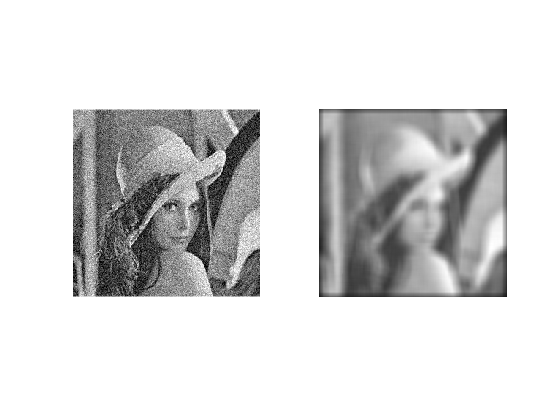

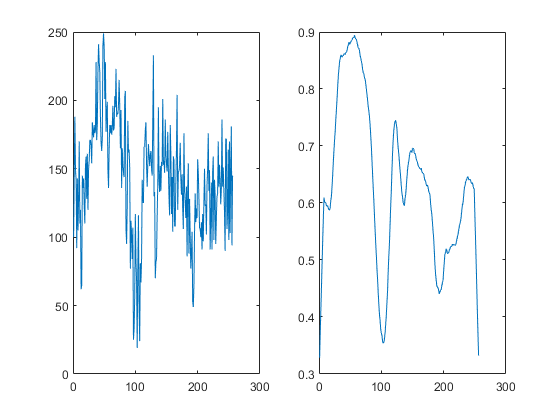

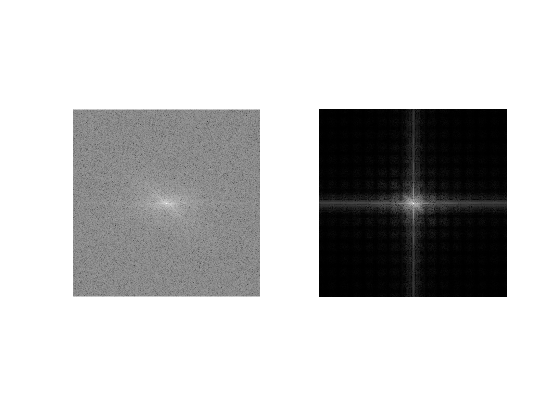

for k=1:m
    taillek=taille(k);
    step=taillek
    numEl=taillek*taillek;
    filtrek=1/numEl*ones(taillek);
    LenaFiltre=filter2(filtrek,LenaBruit,'same');
    LenaFiltre=LenaFiltre/max(LenaFiltre(:));
    % Affichage des deux images en vis à vis
    figure;
    subplot(1,2,1)
    imshow(LenaBruit)
    subplot(1,2,2)
    imshow(LenaFiltre)
    % Extraction d'un profil de pixel
    profil=LenaBruit(:,124);
    profilFiltre=LenaFiltre(:,124);
    % Affichage des profils de pixels
    figure;
    subplot(1,2,1)
    plot(profil)
    subplot(1,2,2)
    plot(profilFiltre)
    % Calcul des TF
    TFBruit=abs(fftshift(fft2(LenaBruit)));
    TFBruit=log(1+TFBruit);
    TFBruit=TFBruit/max(TFBruit(:));
    TFFiltre=abs(fftshift(fft2(LenaFiltre)));
    TFFiltre=log(1+TFFiltre);
    TFFiltre=TFFiltre/max(TFFiltre(:));
    % Affichage des TF
    figure;
    subplot(1,2,1)
    imshow(TFBruit)
    subplot(1,2,2)
    imshow(TFFiltre)
end

Analyser les images résultats obtenus.

## Question 6 :

### Ajouter du bruit poivre et sel de densité 0,05 sur Lena, puis afficher en vis à vis l'image de base et l'image bruitée. Pour cela :

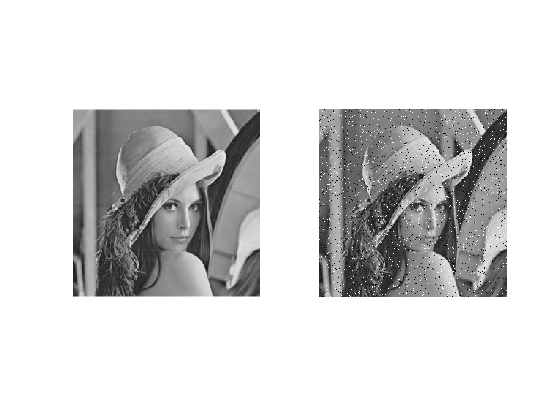

% Bruitage
LenaBruitPoivreSel=imnoise(LenaUnit8,'salt & pepper',0.05);

% Affichage des deux images avec subplot
figure;
subplot(1,2,1)
imshow(LenaUnit8)
subplot(1,2,2)
imshow(LenaBruitPoivreSel)

Cette image de Lena bruitée sera l'image de départ pour les travaux suivants. Penser à l'enregistrer sous un nom explicite.

## Question 7 : 

### Appliquer les filtres moyenneurs et médians 3x3  à l'image bruitée, puis afficher en vis à vis l'image de base, puis les deux images filtrées. Commenter les résultats. Pour cela : 

 Stockage de l'image filtrée par le filtre moyenne 3x3 et affichage en vis à vis :

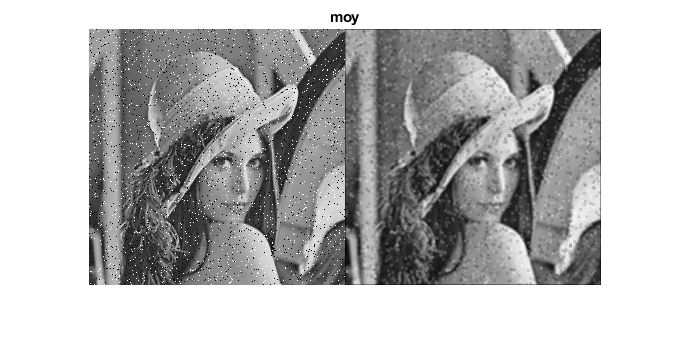

% appliquer le filtre
LenaFiltreMoy=filter2(filtre3x3,LenaBruitPoivreSel,'same');

% affichage à l'aide de imshowpair() et de l'option 'montage'
figure;
imshowpair(LenaBruitPoivreSel,LenaFiltreMoy,'montage');
title('moy')

Appliquer le filtre médian 3x3 à Lena :

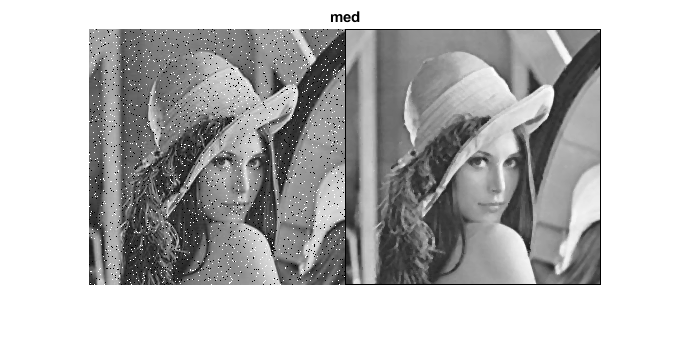

% initialisation de la matrice filtrée à l'aide de zeros()
LenaFiltreMed=zeros(n);
% double boucle sur les pixels 
for i=2:(n-1)
    for j=2:(n-1)
        mat=LenaBruitPoivreSel(i-1:i+1,j-1:j+1);
        med=median(mat(:));
        LenaFiltreMed(i,j)=med;
    end
end
% ici c'est la convolution "valid" 
% affichage à l'aide de imshowpair()
figure;
imshowpair(LenaBruitPoivreSel,LenaFiltreMed,'montage');
title('med')

comparaison avec la fonction deja existante dans la bibliothèque matlab :

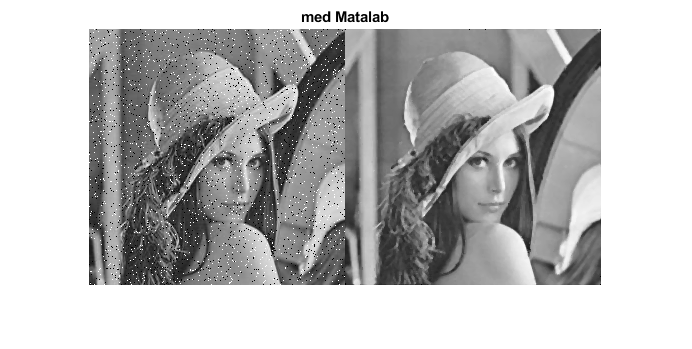

% filtrage à l'aide de medfilt2()
LenaFiltreMedMatlab= medfilt2(LenaBruitPoivreSel);
% affichage à l'aide de imshowpair()
figure;
imshowpair(LenaBruitPoivreSel,LenaFiltreMedMatlab,'montage');
title('med Matalab')

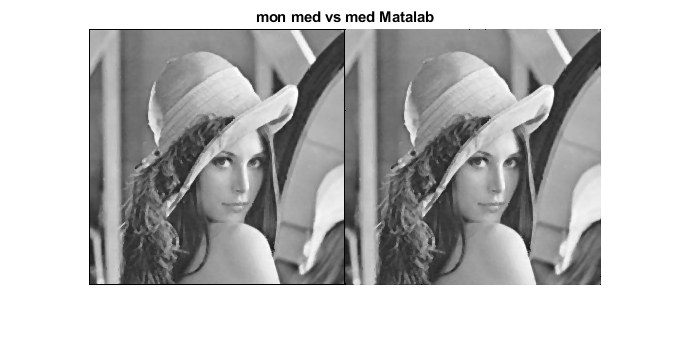


figure;
imshowpair(LenaFiltreMed,LenaFiltreMedMatlab,'montage');
title('mon med vs med Matalab')

% il y a des bords noirs sur mon med 


Conclure sur l'application du filtre médian.